cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\Figures\LWannSupPlot'
cd data\input\

load('Bflat_30min_ann_NetLW.mat')
load('Bflat_30min_ann_outLW.mat')
load('Bflat30min.mat')    
cd ..\output\

%Remove the bad periods of radiation
Bflat30min.OutRad_lw_Wm2(1:12021) = NaN;
Bflat30min.NetRad_Wm2(1:12021) = NaN;
Bflat30min.OutRad_lw_Wm2(46980+134:46980+334) = NaN;
Bflat30min.OutRad_lw_Wm2(47315:47323) = NaN;
Bflat30min.NetRad_lw_Wm2(47315:47323) = NaN;
Bflat30min.OutRad_lw_Wm2(47113) = NaN;

Bflat30min.NetRad_lw_Wm2(55244:60000) = NaN;
Bflat30min.InRad_lw_Wm2(55244:60000) = NaN;
Bflat30min.OutRad_lw_Wm2(55244:60000) = NaN;
Bflat30min.NetRad_Wm2(55244:60000) = NaN;

Bflat30min.NetRad_lw_Wm2_ANN = Bflat_30min_ann_NetLW.LEann_prctile50;
Bflat30min.OutRad_lw_Wm2_ANN  = Bflat_30min_ann_outLW.OutRad_lw_Wm2_ANN;

Bflat30min = retime(Bflat30min, "weekly", 'mean');

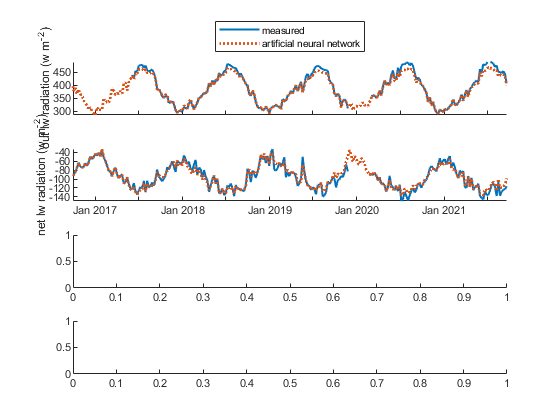

figure
tiledlayout (4,1)

nexttile
hold on 
plot(Bflat30min.Date_Time_MDT, Bflat30min.OutRad_lw_Wm2, ...
     'linewidth', 1.5, 'DisplayName','measured')
plot(Bflat30min.Date_Time_MDT, Bflat30min.OutRad_lw_Wm2_ANN,':', ...
     'linewidth', 2, 'DisplayName','artificial neural network')
ylim([285,490])
legend('Location',"northoutside")
ylabel('out lw radiation (w m^-^2)')
xlim(Bflat_30min_ann_outLW.Date_Time_MDT([1,end]));
xticklabels({})

nexttile
hold on 
plot(Bflat30min.Date_Time_MDT, Bflat30min.NetRad_lw_Wm2, ...
    'linewidth', 1.5, 'DisplayName','measured')
plot(Bflat30min.Date_Time_MDT, Bflat30min.NetRad_lw_Wm2_ANN,':', ...
    'linewidth',  2, 'DisplayName','artificial neural network')

xlim(Bflat_30min_ann_outLW.Date_Time_MDT([1,end]));

% legend
% ylim([180,450])
ylabel('net lw radiation (w m^-^2)')
nexttile
nexttile
print('LW_Radiation_ANN_Plot', '-fillpage','-dpdf') %'-bestfit' -fillpage